clc;
clear all;

# Editable Parameters

Number_of_floor=3;
Number_of_coating_floor=2;

Number_of_calculation_heating=50;
Number_of_calculation_coating=50;
Number_of_calculation_drying=50;

pre_heating_time=5; %(min)

Inlet_coating_sprayrate=144.72; %(g/min)
MCP=0; %(bar)
SAP=1.2; %(bar) % a relier au debit d'atomisation

%D_EC=6.518;  %(mg/API)
Solution_qty=1.27; %(kg)
coating_time=Solution_qty/(Inlet_coating_sprayrate*0.001); %(min)

Size_of_batch=3; %(kg)
Drying_time=3; %(min)
Coating_solution_dry_matter=0.02; %(kg/kg)
Inlet_gas_moisture_water=0.5; %(g water/kg N2)
Inlet_gas_moisture_acetone=0;%(g acetone/kg N2)



Temperature_of_particule=35; %(°C)
Temperature_of_gas_flowrate=40;%(°C)
Inlet_gas_flowrate=200; %(m3/h)








# Modeling parameters


global N_parameter n c r

N_parameter = 6; %(/)


n is the number of floor of the coater

n=Number_of_floor;

c is the number of coating floor inf the coater

c=Number_of_coating_floor;


# Equipments characteristics

global Batch_size Diameter_bed Height_bed Volume_bed Volume_stage
Batch_size=Size_of_batch;%(kg)
Diameter_bed = 0.3; %(m)
Height_bed=0.5; %(m) % A MODIFIER%
Volume_bed = pi*0.25*Height_bed*Diameter_bed^2; %(m^3)
Volume_stage= Volume_bed/n; %(m^3)

# Particle characteristics 

global N_bed Volume_particle Surface_particle Length_particle Mass_particle Diameter_particle ... 
     rho_particle  eps_mf


rho_particle=1070; %(kg/m3)
N_bed=1000000;  %(/)  % Number of particle in the bed     %%%%%%%%%%%%%% A CHANGER %%%%%%%%%%%%%%%%%%%


Diameter_particle=0.001;%(m)


Length_particle=1.3*Diameter_particle;
Surface_particle=0.5*pi*Diameter_particle^2 + pi*Diameter_particle*Length_particle;
Volume_particle=pi*0.25*Length_particle*Diameter_particle^2; %(m^3)
Mass_particle=Volume_particle*rho_particle;

eps_mf=0.42;



# Thermodynamic parameters

global Gas_constant cp_p cp_dry_N2 cp_v DMC cp_c Temp_wb Molecular_weight_acetone Q_lat Volume_N2_stage rho_N2 Mass_N2 ...
    Molecular_weight_N2

Gas_constant =8.314; %(m3*Pa/K*mol)

Molecular_weight_5ASA=153.1354*1e-3; %(kg/mol)
Molecular_weight_N2=28.0134*1e-3; %(kg/mol)
Molecular_weight_acetone=58.08*1e-3; %(kg/mol)
Molecular_weight_PVP=0; %(kg/mol)

cp_p=200; %(J/K*mol)
cp_p=cp_p/Molecular_weight_5ASA; %(J/K*kg)

cp_dry_N2=29.124;%(J/K*mol)
cp_dry_N2=cp_dry_N2/Molecular_weight_N2;%(J/K*kg)


cp_v=75;%(J/K*mol)
cp_v=cp_v/Molecular_weight_acetone; %(J/K*kg)


cp_acetone_liq=125.5;%(J/K*mol) 
cp_c=cp_acetone_liq/Molecular_weight_acetone;

Temp_wb=20+273.15; %(K) & A MODIFIER %


Latent heat of acetone



Q_lat=31.3*1e3; % (J/mol)
Q_lat=Q_lat/Molecular_weight_acetone; %(J/kg)




Volume_N2_stage=Volume_stage-Volume_particle*N_bed/n;% (m^3)
rho_N2=1.185;
Mass_N2=Volume_N2_stage*rho_N2;




# Process input parameters

global Flow_rate_N2 Flow_rate_coating Flow_rate_at absolute_humidity Temp_at Pressure ...
    Gas_moisture_0 Temp_N2_0 


Temp_particle_0=Temperature_of_particule +273.15; %(K)
Temp_N2_0=Temperature_of_gas_flowrate+273.15; %(K)
Particle_moisture_0=0; % (kg acetone/kg particle)

Gas_moisture_0=Inlet_gas_moisture_acetone/1000; % (kg acetone/kg N2)
Coating_mass_0=0; %(/)
Ni_0=N_bed/n;

Flow_rate_N2=Inlet_gas_flowrate/(rho_N2*3600); %(kg/s)
Flow_rate_coating=Inlet_coating_sprayrate/(1000*60);%(kg/s)

%Flow_rate_at=SAP; %(kg/s) %% A modifier%%
Flow_rate_at=0.05*Flow_rate_N2;%(kg/s)

absolute_humidity=0; % (kg acetone/kg N2) at nozzle
Temp_at=20+273.15; %(K)
DMC=Coating_solution_dry_matter; %(kg/kg)

Pressure_out = 1.013*1e5; %(Pa) A MODIFIER
Pressure_in=1.01*Pressure_out; %(Pa)

for i=1:n
    Pressure(i)=(i-1)*(Pressure_out-Pressure_in)/(n-1) + Pressure_in;
end

# Solving differential equations

The matrix coater represents the state of the coater at time t

coater=zeros(n,N_parameter); 

r is the particle exchange rate

r=exchange_rate;% (1/s)

Velocity_N2 = 0.5597

Heigth_mf = 0.0563

Velocity_mf = 0.2919

r = 2.0886



for i=1:n
    coater(i,:)=[Ni_0 Particle_moisture_0 Gas_moisture_0 Coating_mass_0 Temp_particle_0 Temp_N2_0]; 
end


### Pre-heating Part

pre_heating_time=pre_heating_time*60; %(s)
delta_t_heating=pre_heating_time/Number_of_calculation_heating

delta_t_heating = 6

k_heating=Number_of_calculation_heating;


coater

coater = 	1.0e+05 *

    3.3333         0         0         0    0.0031    0.0031
    3.3333         0         0         0    0.0031    0.0031
    3.3333         0         0         0    0.0031    0.0031



%coater_all=pre_heating(coater,k_heating,delta_t_heating);

%coater=coater_all(:,:,end);


for k=1:k_heating
    
    
    tspan= [(k-1)*delta_t_heating k*delta_t_heating];
    

            case i=1, bottom of the coater

    i=1;
   
    z_down=zeros(1,N_parameter);
    z_up=coater(i+1,:);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    coater(i,:)=z(end,:);
    

            General case

    
   for i=2:n-1
    
    z_down=coater(i-1,:);
    z_up=coater(i+1,:);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    
    
    coater(i,:)=z(end,:);
     
   end


            case i=n, top of the coater

  
    i=n;
    z_down=coater(i-1,:);
    z_up=zeros(1,N_parameter);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    coater(i,:)=z(end,:);

        The matrix 3D coater_all recovers the data at every time t

     
   coater_all(:,:,k)=coater;

      

   t_plot(k)=tspan(2);
end

### Spraying Part


coating_time=coating_time*60; %(s)
delta_t_coating=coating_time/Number_of_calculation_coating

delta_t_coating = 10.5307


k_coating=k_heating + Number_of_calculation_coating;
k_heating=k_heating+1;

coater

coater = 	1.0e+05 *

    3.3333   -0.0000   -0.0000         0    0.0031    0.0031
    3.3333   -0.0000   -0.0000         0    0.0031    0.0031
    3.3333   -0.0000   -0.0000         0    0.0031    0.0031


for k=k_heating:k_coating
    
    
    tspan= [pre_heating_time+(k-k_heating)*delta_t_coating pre_heating_time+(k-k_heating+1)*delta_t_coating];
    

            case i=1, bottom of the coater

    i=1;
   
    z_down=zeros(1,N_parameter);
    z_up=coater(i+1,:);
    z_i=coater(i,:);

    [t,z]=ode15s(@(t,z) model(t,z,z_down,z_up,i), tspan, z_i);
  
    
    coater(i,:)=z(end,:);
    

            General case

    
   for i=2:n-1
    
    z_down=coater(i-1,:);
    z_up=coater(i+1,:);
    z_i=coater(i,:);

        [t,z]=ode15s(@(t,z) model(t,z,z_down,z_up,i), tspan, z_i);
    
    
    coater(i,:)=z(end,:);
     
   end


            case i=n, top of the coater

  
    i=n;
    z_down=coater(i-1,:);
    z_up=zeros(1,N_parameter);
    z_i=coater(i,:);
    

        [t,z]=ode15s(@(t,z) model(t,z,z_down,z_up,i), tspan, z_i);

    
    coater(i,:)=z(end,:);

        The matrix 3D coater_all recovers the data at every time t

     
   coater_all(:,:,k)=coater;
   

   t_plot(k)=tspan(2);
end

#### Drying part

k_drying=k_coating + Number_of_calculation_drying;
k_coating=k_coating+1;

Drying_time=Drying_time*60; %(s)

delta_t_drying=Drying_time/Number_of_calculation_drying

delta_t_drying = 3.6000


 
for k=k_coating:k_drying
    
    
    tspan= [ pre_heating_time+coating_time+(k-k_coating)*delta_t_drying pre_heating_time+...
        coating_time+(k-k_coating+1)*delta_t_drying];
    

            case i=1, bottom of the coater

    i=1;
   
    z_down=zeros(1,N_parameter);
    z_up=coater(i+1,:);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    coater(i,:)=z(end,:);
    

            General case

    
   for i=2:n-1
    
    z_down=coater(i-1,:);
    z_up=coater(i+1,:);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    
    
    coater(i,:)=z(end,:);
     
   end


            case i=n, top of the coater

  
    i=n;
    z_down=coater(i-1,:);
    z_up=zeros(1,N_parameter);
    z_i=coater(i,:);
    

         [t,z]=ode15s(@(t,z) model_drying(t,z,z_down,z_up,i), tspan, z_i);   

    coater(i,:)=z(end,:);

        The matrix 3D coater_all recovers the data at every time t

     
   coater_all(:,:,k)=coater;
      

   t_plot(k)=tspan(2);
end


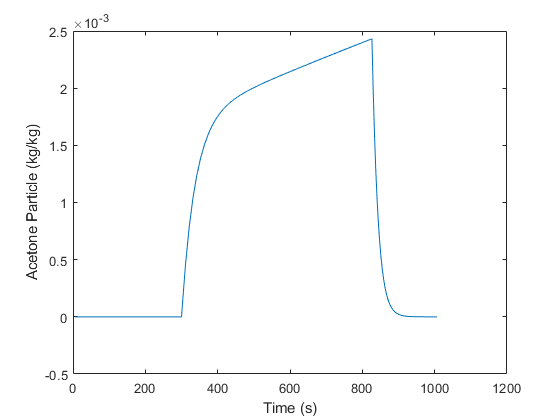



Outlet_Temperature(:)=coater_all(end,6,:)-273.15;
Inlet_Temperature(:)=coater_all(1,6,:)-273.15;
Moy_Temperature(:)=mean(coater_all(:,6,:)-273.15);

Outlet_Particle_Temperature(:)=coater_all(end,5,:)-273.15;
Inlet_Particle_Temperature(:)=coater_all(1,5,:)-273.15;
Moy_Particle_Temperature(:)=mean(coater_all(:,5,:)-273.15);

Total_coating(:)=sum(coater_all(:,4,:).*coater_all(:,1,:)*Mass_particle);


Acetone_particle(:)=sum(coater_all(:,2,:).*coater_all(:,1,:)*Mass_particle);
Acetone_gas(:)=sum(coater_all(:,3,:)*Mass_N2);



plot (t_plot,Acetone_particle)
xlabel('Time (s)')
ylabel('Acetone Particle (kg/kg)')

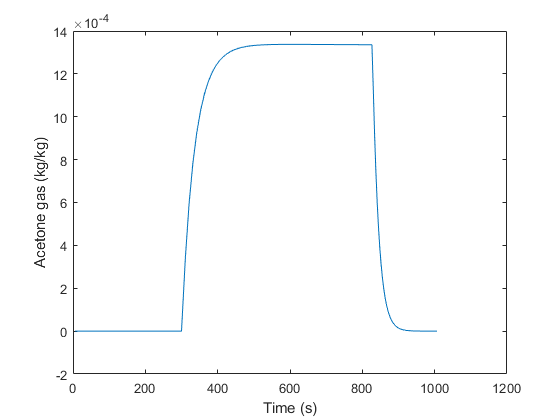


plot (t_plot,Acetone_gas)
xlabel('Time (s)')
ylabel('Acetone gas (kg/kg)')

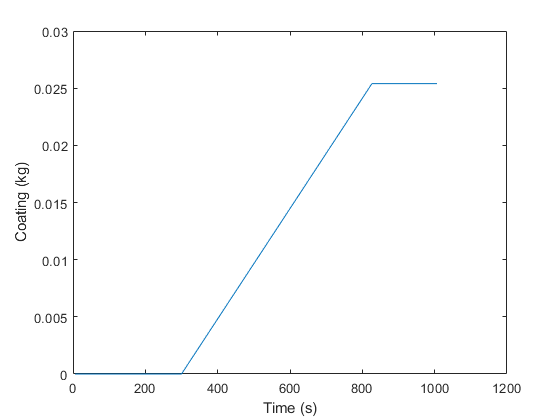


plot (t_plot,Total_coating)
xlabel('Time (s)')
ylabel('Coating (kg)')

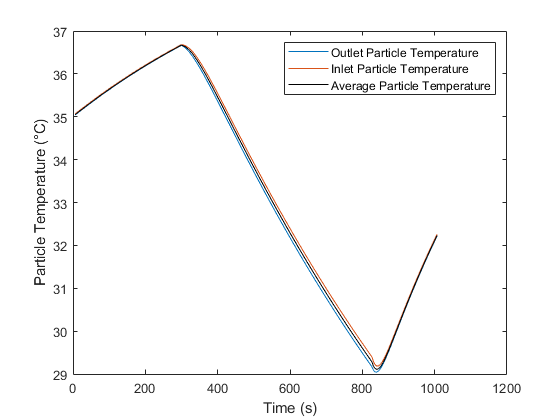


plot (t_plot,Outlet_Particle_Temperature)
hold on
plot (t_plot,Inlet_Particle_Temperature)
plot (t_plot,Moy_Particle_Temperature,'k')

xlabel('Time (s)')
ylabel('Particle Temperature (°C)')
legend ('Outlet Particle Temperature', 'Inlet Particle Temperature', 'Average Particle Temperature')
hold off

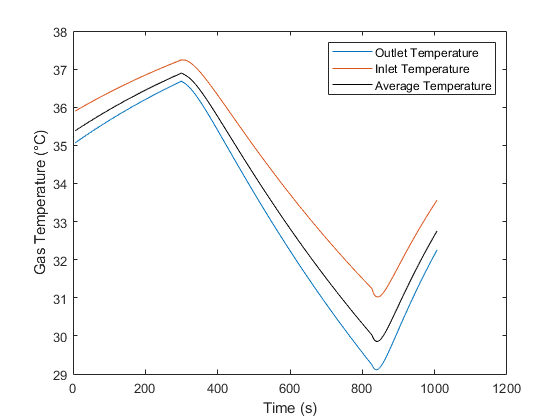


plot (t_plot,Outlet_Temperature)
hold on
plot(t_plot,Inlet_Temperature)
plot(t_plot,Moy_Temperature,'k')
xlabel('Time (s)')
ylabel('Gas Temperature (°C)')

legend ('Outlet Temperature', 'Inlet Temperature', 'Average Temperature')

coater_end=coater_all(:,:,end);